# NR Cell Performance Evaluation with MIMO

This example shows how to model a 5G New Radio (NR) cell with multiple-input multiple-output (MIMO) antenna configuration and evaluate the network performance. It uses multi-port channel state information reference signals (CSI-RS) to measure downlink (DL) channel characteristics. Alternatively, you can use sounding reference signals (SRS) for DL channel measurements. To measure uplink (UL) channel characteristics, the example uses SRS signals. The gNB node uses this measured channel characteristics to make MIMO scheduling decisions.

## Introduction

MIMO improves network performance by improving the cell throughput and reliability. The example performs layer mapping and precoding to utilize MIMO in the DL and UL directions.

This example models:

- Single-codeword DL spatial multiplexing to perform multi-layer transmission. Single-codeword limits the number of transmission layers to 4.

- Precoding to map the transmission layers to antenna ports. The example assumes one-to-one mapping from antenna ports to physical antennas.

- DL channel quality measurement by UEs based on the multi-port CSI-RS received from the gNB. All the UEs in the cell measure on same CSI-RS resource.

- DL channel quality measurement by the gNB node based on the multi-port SRS signals received from the UEs. It includes the DL rank, the precoding matrix and the modulation and coding scheme (MCS). 

- UL channel quality measurement by gNB based on the multi-port SRS received from the UEs. 

- DL rank indicator (RI), precoding matrix indicator (PMI), and channel quality indicator (CQI) reporting by UEs. The example supports Type-1 single-panel codebook for PMI.

- 3GPP TR 38.901 channel model.

- Slot-based DL and UL scheduling.

- Link-to-system-mapping-based abstract physical layer (PHY).

This example assumes that nodes send the control packets (buffer status report (BSR), DL assignment, UL grants, PDSCH feedback, and CSI report) out of band, eliminating the requirement for transmission resources and ensuring error-free reception.

## **MIMO**

 The key aspects of MIMO include spatial multiplexing, precoding, channel measurement and reporting.

### **Spatial multiplexing**

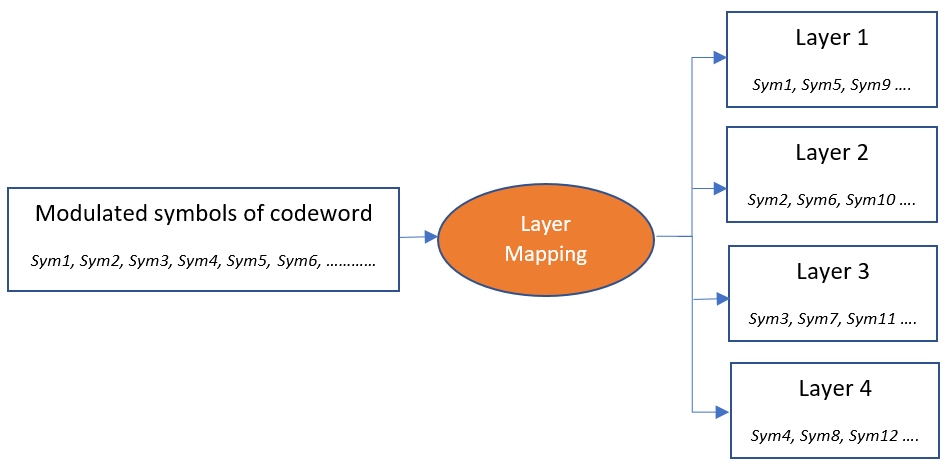

Spatial multiplexing utilizes MIMO to perform multi-layer transmission. The minimum of number of transmit and receive antennas limits the number of layers (or maximum rank). The layer mapping process maps the modulated symbols of the codeword onto different layers. It maps every $n^{\textrm{th}}$ symbol of the codeword to $n^{\textrm{th}}$ layer. For instance, this figure shows the mapping of a codeword onto four layers.

Furthermore, in both the UL and DL direction, NR specification allows for two codewords and supports up to a maximum of 8 transmission layers. The example currently supports only a single codeword for both DL and UL.

### Precoding

    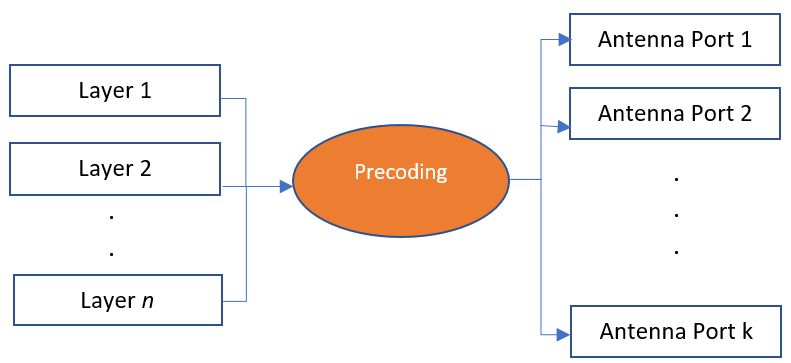      

Precoding, which follows the layer mapping, maps the transmission layers to antenna ports. Precoding applies a precoding matrix to the transmission layers and outputs data streams to the antenna ports.

### Channel measurement and reporting

It consists of DL channel measurement and reporting by the UEs and UL channel measurement by gNB.

    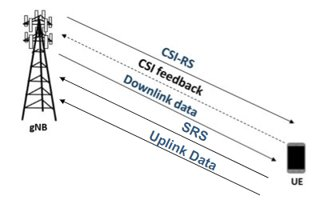

#### DL channel measurement using CSI-RS and reporting

To measure the DL channel characteristics, UEs use CSI-RS. A gNB automatically configures a full bandwidth CSI-RS resource which all the UEs in the cell use. gNB sets the CSI-RS configuration such that number of CSI-RS ports are equal to number of transmit antennas on gNB. The periodicity for CSI-RS transmission is 10 slots for frequency division duplex (FDD) mode. For time division duplex (TDD) mode, the periodicity is a multiple of the length of the DL-UL pattern (in slots). In this case, the periodicity is the least value greater than or equal to 10 slots.

CSI reporting is the process by which a UE, for DL transmissions, advises a suitable number of transmission layers (rank), PMI, and CQI values to the gNB. The UE estimates these values by performing channel measurements on its configured CSI-RS resources. For more details, see the [5G NR Downlink CSI Reporting](docid:5g_ug#mw_d1f89a94-4ef9-4f57-9301-212f082e187e) example. The gNB scheduler uses this advice to decide the number of transmission layers, precoding matrix, and modulation and coding scheme (MCS) for PDSCHs.

#### **DL channel measurement using SRS for TDD system**

In TDD systems, where both UL and DL transmissions operate within the same frequency band, you can also use SRS signals for measuring the DL channel characteristics. The radio channel shows identical properties in both UL and DL directions, exhibiting reciprocity. The reciprocity-based precoding technique exploits this property to derive a channel estimate from an uplink transmission, enabling the determination of parameters like precoder for a downlink transmission.

The gNB node estimates the uplink channel from SRS signals transmitted by the UE nodes. Using TDD reciprocity, the gNB then estimates the DL channel. This DL channel estimation aids in deriving the DL CSI, which includes the rank, precoder, and MCS for DL transmissions.

#### UL channel measurement

The UL channel measurements serve as an important input to the scheduler to decide the number of transmission layers, precoding matrix and MCS for PUSCHs.

To measure UL channel characteristics, gNB uses sounding reference signals (SRS). The gNB sets the SRS configuration such that number of SRS ports are equal to number of transmit antennas on UE. UEs transmit SRS periodically. The SRS transmission periodicity is a multiple of 'N' where 'N' is the interval in slots at which the gNB reserves one symbol for the SRS resource across the entire bandwidth. 'N' is 5 for FDD. For TDD, 'N' is the smallest value >= 5 slots such that it is multiple of length of the DL-UL pattern in slots. The gNB configures the UEs to share the reservation of SRS by differing the comb offset, cyclic shift, or transmission time. The comb size and maximum cyclic shift are both assumed as 4. In this case, gNB can configure up to 16 connected UEs to transmit SRS with a periodicity as 'N' slots. If more than 16 UEs are connected, increase the SRS transmission periodicity to the next higher valid value (a multiple of 'N'). For more details on SRS transmission periodicity, see the [nrGNB](docid:5g_ref#mw_fe5aba91-dc51-4965-8806-828df3b56715).

## Scenario simulation

Check if the Communications Toolbox Wireless Network Simulation Library support package is installed. If the support package is not installed, MATLAB® returns an error with a link to download and install the support package.

wirelessnetworkSupportPackageCheck

Create a wireless network simulator.

rng("default") % Reset the random number generator
numFrameSimulation = 100; % Simulation time in terms of number of 10 ms frames
networkSimulator = wirelessNetworkSimulator.init;

To use full PHY, set the PHY type, `phyAbstractionType`, to "`none"`. To use abstract PHY, set `phyAbstractionType` to "`linkToSystemMapping"`. All the nodes (gNB and UEs) must use the same PHY processing method.

phyAbstractionType = "linkToSystemMapping";

To use SRS-based DL SU-MIMO, set the `csiMeasurementSignalDLType` to "`SRS`". The default value of the `csiMeasurementSignalDLType` is "`CSI-RS`".

csiMeasurementSignalDLType = "CSI-RS";

Set `duplexType` to "`TDD`" or "`FDD`". For SRS-based DL SU-MIMO, you must set `duplexType` to "`TDD`".

duplexType = "FDD";

Specify DL and UL time division configuration for TDD mode.

tddConfig = struct(DLULPeriodicity=5,NumDLSlots=2,NumDLSymbols=12,NumULSymbols=1,NumULSlots=2);

Create a gNB node and specify its position, carrier frequency, channel bandwidth, subcarrier spacing, duplex mode, TDD configuration, number of transmit and receive antennas, receive gain, and sounding reference signal (SRS) transmission periodicity (in slots) for all connecting UE nodes.

gNB = nrGNB(Position=[0 0 30],CarrierFrequency=2.6e9,ChannelBandwidth=5e6,SubcarrierSpacing=15e3,DuplexMode=duplexType,DLULConfigTDD=tddConfig, ...
    NumTransmitAntennas=16,NumReceiveAntennas=16,ReceiveGain=11,PHYAbstractionMethod=phyAbstractionType,SRSPeriodicityUE=40);
configureScheduler(gNB,CSIMeasurementSignalDL=csiMeasurementSignalDLType);

Create 4 UE nodes and specify their name, position, number of transmit and receive antennas, and receive gain.

uePositions = [300 0 3; 700 0 3; 1200 0 3; 3000 0 3];
ueNames = "UE-" + (1:size(uePositions,1));
UEs = nrUE(Name=ueNames,Position=uePositions,NumTransmitAntennas=4,NumReceiveAntennas=4,ReceiveGain=11,PHYAbstractionMethod=phyAbstractionType);

Connect the UE nodes to gNB. Specify the radio link control (RLC) bearer configuration to establish an RLC bearer between the gNB and each UE node. Set the DL channel status information (CSI) report periodicity to 80 slots.

rlcBearer = nrRLCBearerConfig(SNFieldLength=6,BucketSizeDuration=10); % Create an RLC bearer configuration object.
connectUE(gNB,UEs,RLCBearerConfig=rlcBearer,CSIReportPeriodicity=80)  % Establish an RLC bearer between the gNB and UE nodes

Set the periodic DL and UL application traffic pattern for UEs.

appDataRate = 40000; % Application data rate in kilobits per second (kbps)
for ueIdx = 1:numel(UEs)
    % Install the DL application traffic on gNB for the UE node
    dlApp = networkTrafficOnOff(GeneratePacket=true,OnTime=numFrameSimulation*10e-3,...
        OffTime=0,DataRate=appDataRate);
    addTrafficSource(gNB,dlApp,DestinationNode=UEs(ueIdx))

    % Install the UL application traffic on the UE node for the gNB
    ulApp = networkTrafficOnOff(GeneratePacket=true,OnTime=numFrameSimulation*10e-3,...
        OffTime=0,DataRate=appDataRate);
    addTrafficSource(UEs(ueIdx),ulApp)
end

Add the gNB and UE nodes to the network simulator.

addNodes(networkSimulator,gNB)
addNodes(networkSimulator,UEs)

Use 3GPP TR 38.901 channel model for all links. You can also run the example with a CDL channel model.

channelModel = "3GPP TR 38.901";

if strcmp(channelModel,"CDL channel")
    % Create an N-by-N array of link-level channels, where N represents the number of
    % nodes in the cell. An element at index (i,j) contains the channel instance
    % from node i to node j. If the element at index (i,j) is empty, it indicates
    % the absence of a channel from node i to node j. Here i and j represents the
    % node IDs.
    channelConfig = struct(DelayProfile="CDL-C", DelaySpread=300e-9);
    channels = hNRCreateCDLChannels(channelConfig,gNB,UEs);

    % Create a custom channel model using channels and install the custom
    % channel on the simulator. Network simulator applies the channel to a
    % packet in transit before passing it to the receiver.
    channel = hNRCustomChannelModel(channels,struct(PHYAbstractionMethod=phyAbstractionType));
    addChannelModel(networkSimulator,@channel.applyChannelModel)
else
    % Model a rural macro scenario, as defined in the 3GPP TR 38.901 channel
    % model, using the h38901Channel object.

    % Define scenario boundaries
    pos = reshape([gNB.Position UEs.Position],3,[]);
    minX = min(pos(1,:));          % x-coordinate of the left edge of the scenario in meters
    minY = min(pos(2,:));          % y-coordinate of the bottom edge of the scenario in meters
    width = max(pos(1,:)) - minX;  % Width (right edge of the 2D scenario) in meters, given as maxX - minX
    height = max(pos(2,:)) - minY; % Height (top edge of the 2D scenario) in meters, given as maxY - minY

    % Create the channel model
    channel = h38901Channel(Scenario="RMa",ScenarioExtents=[minX minY width height]);
    % Add the channel model to the simulator
    addChannelModel(networkSimulator,@channel.channelFunction);
    connectNodes(channel,networkSimulator);
end

Set the `enableTraces` to `true` to log the traces. When you set the `enableTraces` parameter to false, the simulation does not log any traces. However, setting `enableTraces` to `false` can speed up the simulation.

enableTraces = true;

Set up scheduling logger and PHY logger.

if enableTraces
    % Create an object to log scheduler traces
    simSchedulingLogger = helperNRSchedulingLogger(numFrameSimulation,gNB,UEs);
    % Create an object to log for PHY traces
    simPhyLogger = helperNRPhyLogger(numFrameSimulation,gNB,UEs);
end

Set the number of updates per second for the metric plots.

numMetricPlotUpdates = 10; % Updates plots every 100 milliseconds

Set up metric visualizer.

metricsVisualizer = helperNRMetricsVisualizer(gNB,UEs,RefreshRate=numMetricPlotUpdates,...
    PlotSchedulerMetrics=true,PlotPhyMetrics=true);

Write the logs to MAT-file. You can use these logs for post-simulation analysis.

simulationLogFile = "simulationLogs"; % For logging the simulation traces

Run the simulation for the specified `numFrameSimulation` frames.

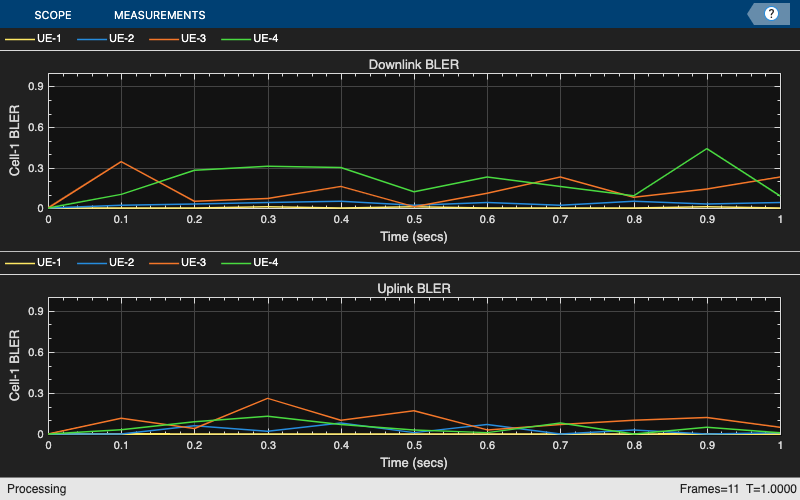

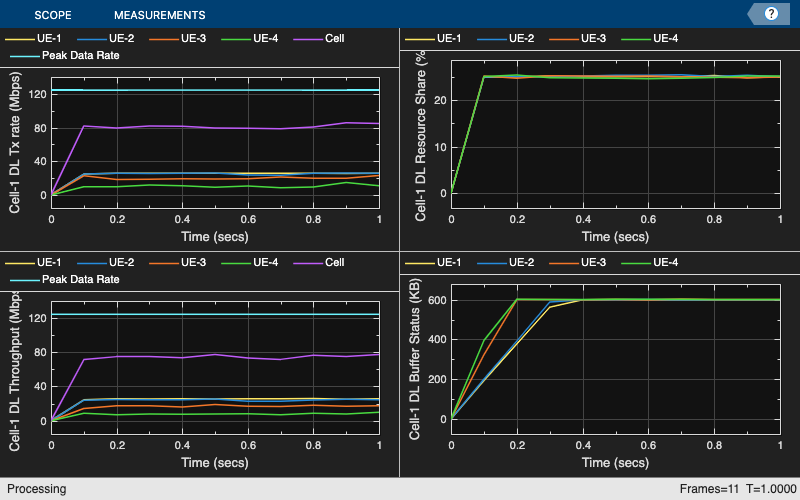

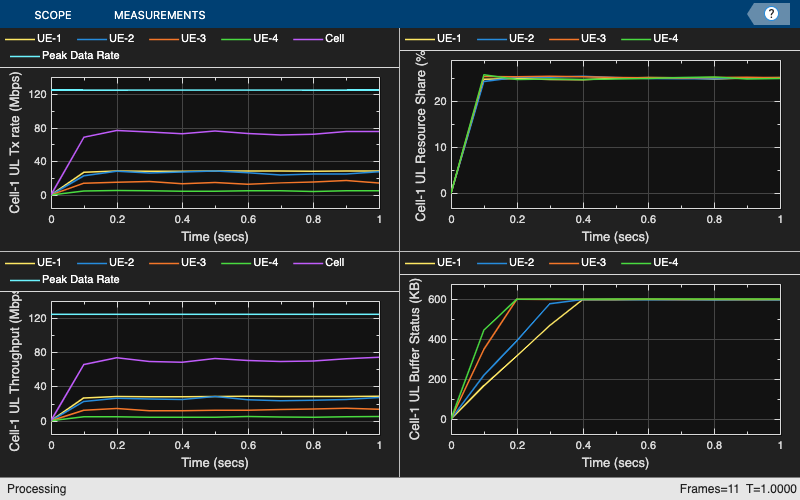

% Calculate the simulation duration (in seconds)
simulationTime = numFrameSimulation * 1e-2;
% Run the simulation
run(networkSimulator,simulationTime);

Read per-node statistics.

gNBStats = statistics(gNB);
ueStats = statistics(UEs);

At the end of the simulation, compare the achieved values for system performance indicators with theoretical peak values (considering zero overheads). Performance indicators displayed are achieved data rate (UL and DL), achieved spectral efficiency (UL and DL), and block error rate (BLER) observed for UEs (UL and DL). The calculated peak values are in accordance with 3GPP TR 37.910.

displayPerformanceIndicators(metricsVisualizer)

Peak UL throughput: 124.42 Mbps. Achieved cell UL throughput: 70.57 Mbps
Achieved UL throughput for each UE: [28.12        25.12         12.9         4.44]
Peak UL spectral efficiency: 24.88 bits/s/Hz. Achieved UL spectral efficiency for cell: 14.11 bits/s/Hz 
Block error rate for each UE in the UL direction: [0       0.028       0.105        0.05]

Peak DL throughput: 124.42 Mbps. Achieved cell DL throughput: 74.67 Mbps
Achieved DL throughput for each UE: [25.42        24.26           17            8]
Peak DL spectral efficiency: 24.88 bits/s/Hz. Achieved DL spectral efficiency for cell: 14.93 bits/s/Hz
Block error rate for each UE in the DL direction: [0.003       0.034       0.142       0.212]



## Simulation Visualization

To evaluate the performance of the cell, the example includes various runtime visualizations. For further details on the runtime visualizations presented, refer to [Simulation Visualization](docid:5g_ug#mw_73df19f5-3900-4a27-84a4-8d702b76679e).

## Simulation Logs

This example stores the simulation logs in MAT-flies for the post-simulation analysis. The MAT-file `simulationLogFile` saves the per time step logs, the scheduling assignment logs, and the PHY reception logs. After the simulation, open the file to load `DLTimeStepLogs`, `ULTimeStepLogs`, `SchedulingAssignmentLogs`, `PhyReceptionLogs` in the workspace.

**Time step logs:** Both the DL and UL time step logs follow the same format. The table shows sample time step entries.

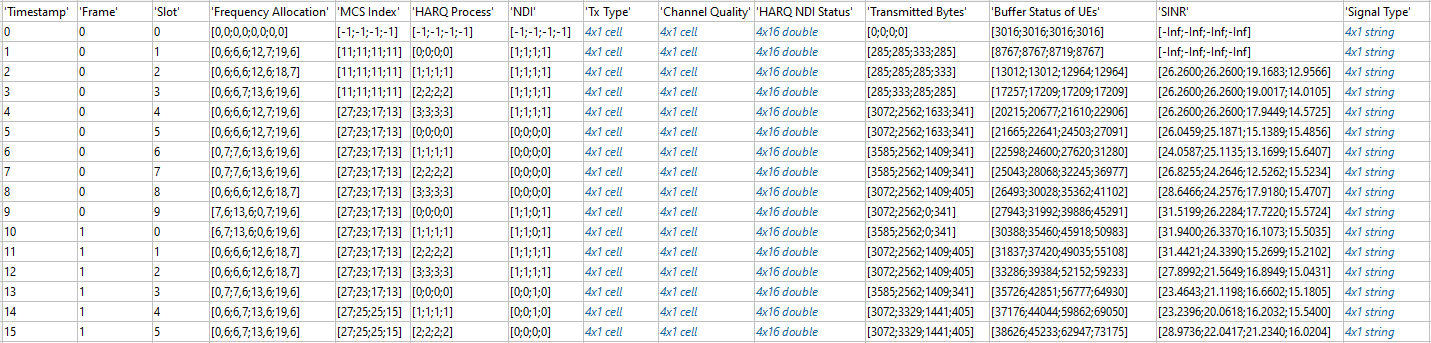

Each row of the table represents a slot and contains the following information:

- *Timestamp*: Time (in milliseconds) since the start of simulation.

- *Frame*: Frame number.

- *Slot*: Slot number in the frame.

- *Type*: Slot type. The values 'DL', 'UL', and 'S' indicate the downlink slot, uplink slot, and special slot, respectively.

- *Frequency Allocation*: N-by-P matrix. N is the number of UEs. For frequency resource allocation type-1, P is 2. The first element of frequency resource allocation indicates the starting RB. The second element indicates the number of RBs allocated. For example, [0,6;6,6;12,7;19,6] indicates this: the scheduler has assigned 6 RBs (starting from 0) to UE-1, 6 RBs (starting from 6) to UE-2, 7 RBs (starting from 12) to UE-3, and 6 RBs (starting from 19) to UE-4. For frequency resource allocation type-0, P is the number of resource block groups (RBGs). The scheduler assigns an RBG to a particular UE by setting the corresponding bit to 1. For example, [ 0 0 1 1 0 1 0 1 0 1 0 0 0; 1 1 0 0 0 0 0 0 0 0 1 0 0; 0 0 0 0 1 0 1 0 1 0 0 1 1; 0 0 0 0 0 0 0 0 0 0 0 0 0] indicates that the bandwidth has 13 RBGs. The scheduler has assigned the RBG indices 2, 3, 5, 7, and 9 to UE-1, the RBG indices 0, 1, and 10 to UE-2, and the RBG indices 4, 6, 8, 11, and 12 to UE-3. The scheduler has not assigned any RBGs to UE-4.

- *MCS*: Column vector of length *N,* where *N* is the number of UEs. Each value corresponds to the modulation and coding scheme (MCS) index for the transmission. For example, [10;12;8;-1] indicates these: a) the scheduler has assigned the resources to UE-1, UE-2, and UE-3 for this slot and b) UE-1, UE-2 AND UE-3 use the MCS values 10, 12, and 8, respectively. The MCS index corresponds to 3GPP TS 38.214 - Table 5.1.3.1-2.

- *HARQ Process*: Column vector of length *N,* where *N* is the number of UEs. The value is the HARQ process ID used by UE for the transmission. For example, [0;3;6;-1] indicates these: a) the scheduler has assigned the resources to UE-1, UE-2, and UE-3 for this slot and b) UE-1, UE-2 AND UE-3 use the HARQ process IDs 0, 3, and 6, respectively.

- *NDI*: Column vector of length *N,* where *N* is the number of UEs. The value is the new data indicator (NDI) flag value in the assignment for transmission. For example, [0;0;1;-1] indicates these: a) The scheduler has assigned the resources to UE-1, UE-2, and UE-3 for this slot and b) UE-1, UE-2, and UE-3 use the NDI flag values 0, 0, and 1, respectively. The NDI flag determines whether the UEs have used a new transmission or a retransmission.

- *Tx Type*: Cell array of length *N,* where *N* is the number of UEs. Tx Type specifies the transmission type (new transmission or retransmission), specified as one of these values: '`newTx`', '`reTx`', or '`noTx`'. '`noTx`' indicates that the scheduler has not allocated the resources to the UE.  For example, {'`newTx`' '`newTx`' '`reTx`' '`noTx`'} indicates that the scheduler has assigned the resources to UE-1, UE-2, and UE-3 for this slot. UE-1 and UE-2 transmit a new packet from the specified HARQ process while UE-3 retransmits the packet in the buffer of the specified HARQ process.

- *Channel Quality*: Cell array of length *N*, where *N* is the number of UEs. An element at index *i* contains the channel quality information for UE with RNTI *i*.

- *HARQ NDI Status*: *N-by-P* matrix, where *N* is the number of UEs and *P* is the number of HARQ processes on UEs. A matrix element at position *(i, j)* is the last received NDI flag at UE *i* for HARQ process ID *j*. For new transmissions, this value and the NDI flag in the assignment must toggle. For example, in slot 4 of frame 0 described in the scheduling log, the last NDI flag value for HARQ ID 3 at UE-1 is 1. To indicate a new transmission, the NDI flag value changes to 0.

- *Transmitted Bytes*: Column vector of length *N,* where *N* is the number of UEs. The values represent MAC bytes transmitted per UE in this slot. The value only includes new transmission bytes. For retransmissions, the value is zero.

- *Buffer Status of UEs*: Column vector of length *N,* where *N* is the number of UEs. The values represent the amount of pending buffer per UE.

- SINR: Column vector of length N, where N represents the number of UE nodes. The values denote the effective signal to interference plus noise ratio received at the gNB or UE node. An SINR value of -Inf indicates that the simulator did not log the value at a particular slot.

- *Signal Type: *A string vector of length N, where N is the number of UE nodes. Each string represents the signal types for a UE node, which can include PDSCH, CSIRS, PUSCH, SRS, or combinations of these used in specific slots. An empty string indicates no transmission for that UE node.

**Scheduling assignment logs:** A log of all the scheduling assignments and related information. The table shows sample log entries.

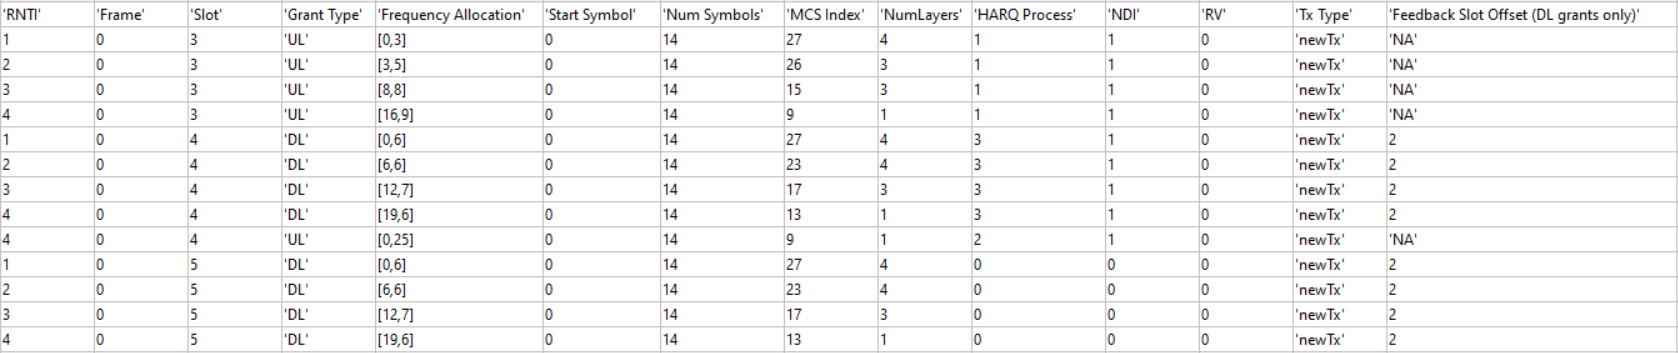

Each row of the table represents a DL or UL allocation grant and contains these information:

- *RNTI*: Radio network temporary identifier of UE.

- *Frame*: Frame number.

- *Slot*: Slot number in the frame.

- *Grant Type*: Grant type as 'DL' or 'UL'.

- *Frequency Allocation*: Row vector of length P. For frequency resource allocation type-1, P is 2. For frequency resource allocation type-0, P is the number of RBGs.

- *Start Symbol*: Start symbol for the transmission.

- *Num Symbols*: Number of symbols for the transmission.

- *MCS Index*: Modulation and coding scheme (MCS) index for the transmission.

- *NumLayers: *Number of spatial layers for the transmission.

- *HARQ Process*: HARQ process ID used for the transmission.

- *NDI*: NDI flag value for transmission.

- *RV: *Redundancy version for the transmission.

- *Tx Type*: Transmission type, specified as one of these values: '`newTx`', '`reTx`'.

- *Feedback Slot Offset (DL grants only)*: Slot offset for the feedback of PDSCH transmission.

**PHY reception logs:** A log of Phy packet reception information observed in the uplink and downlink directions. This table shows the sample log entries.

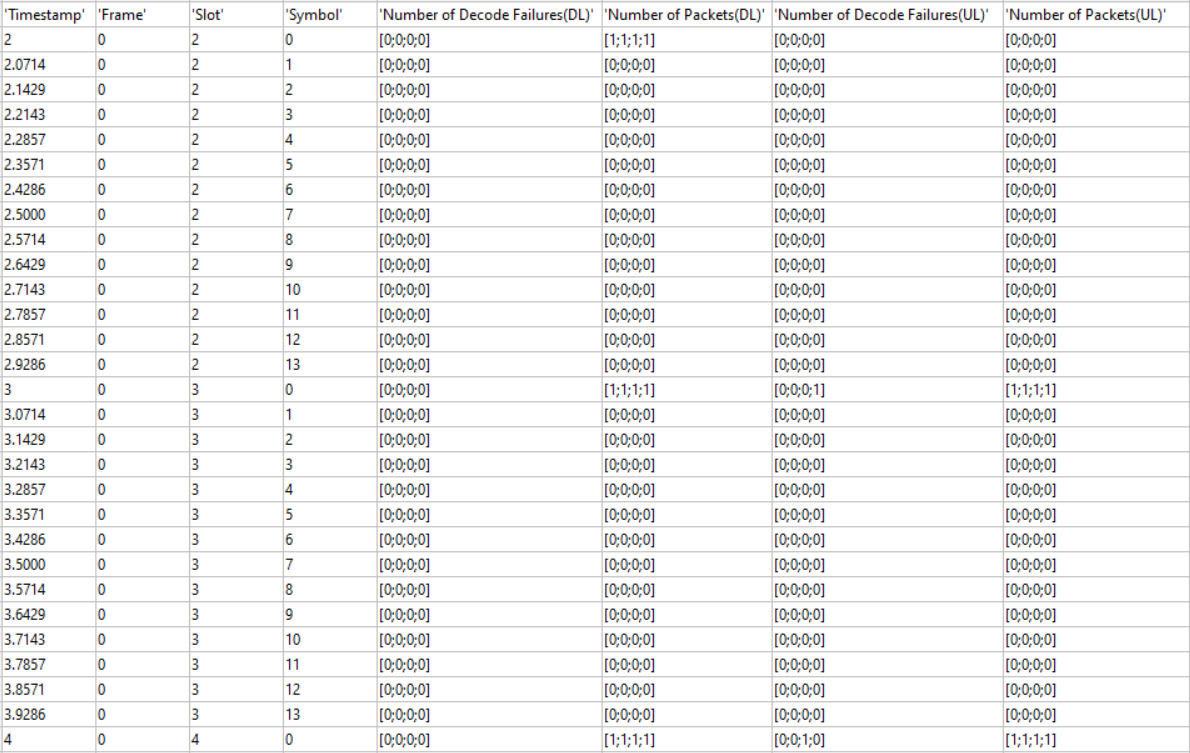

Each row of the table represents a slot and contains the following information:

- *Timestamp*: Time (in milliseconds) since the start of simulation.

- *Frame*: Frame number.

- *Slot*: Slot number in the frame.

- *Symbol*: Symbol number in the slot.

- *Number of Decode Failures (DL)*: Column vector of length *N,* where *N* is the number of UEs. The values represent the number of decode failures at the UE nodes in this slot.

- *Number of Packets (DL)*: Column vector of length *N,* where *N* is the number of UEs. The values represent the number of packets received at the UE nodes in this slot.

- *Number of Decode Failures (UL)*: Column vector of length *N,* where *N* is the number of UE nodes. The values represent the number of decode failures at the gNB for each UE node in this slot.

- *Number of Packets (UL)*: Column vector of length *N,* where *N* is the number of UE nodes. The values represent the number of packets received at the gNB for each UE node in this slot.

Save the simulation logs in a MAT file.

if enableTraces
    simulationLogs = cell(1,1);
    if gNB.DuplexMode == "FDD"
        logInfo = struct(DLTimeStepLogs=[],ULTimeStepLogs=[],...
            SchedulingAssignmentLogs=[],PhyReceptionLogs=[]);
        [logInfo.DLTimeStepLogs,logInfo.ULTimeStepLogs] = getSchedulingLogs(simSchedulingLogger);
    else % TDD
        logInfo = struct(TimeStepLogs=[],SchedulingAssignmentLogs=[],PhyReceptionLogs=[]);
        logInfo.TimeStepLogs = getSchedulingLogs(simSchedulingLogger);
    end
    % Obtain the scheduling assignments log
    logInfo.SchedulingAssignmentLogs = getGrantLogs(simSchedulingLogger);
    % Obtain the Phy reception logs
    logInfo.PhyReceptionLogs = getReceptionLogs(simPhyLogger);
    % Save simulation logs in a MAT-file
    simulationLogs{1} = logInfo;
    save(simulationLogFile,"simulationLogs")
end

## Further Exploration

Try running the example with these modifications.

- Modify this example to customize the CDL channel model parameters by using the output of a ray tracing analysis. Refer to the [CellPerformanceWithRayTrace.m](matlab:edit('CellPerformanceWithRayTrace.m')) script, which demonstrates this workflow. The script follows the [CDL Channel Model Customization with Ray Tracing](docid:5g_ug#mw_788a51e3-b40f-402d-ace3-d4e701ea8781) example to configure the 'Custom' delay profile of nrCDLChannel object.

- Configure link adaptation parameters and analyze their impact on the key performance indicators. For more information on this, see `LinkAdaptationConfigDL` in [`configureScheduler`](docid:5g_ref#mw_432e1e77-a65c-49b3-947f-66d30de4e50b).

- Configure an SRS-based DL SU-MIMO and analyze its impact on the key performance indicators. For more information about the SRS-based DL SU-MIMO, see the `CSIMeasurementSignalDL` name-value argument of the [`configureScheduler`](docid:5g_ref#mw_432e1e77-a65c-49b3-947f-66d30de4e50b) object function.

- Compare the wideband SINR for CSI-RS and SRS-based DL measurements. See the [AnalyzeDownlinkSINRUsingCSIRSAndSRS.m](matlab:edit('AnalyzeDownlinkSINRUsingCSIRSAndSRS.m')) script which demonstrates this workflow. This plot compares the SINRs for the SRS and CSI-RS signals in TDD systems. The plot shows similar SINRs for zero forcing precoding using SRS compared to codebook single panel type I CSI-RS. The channel model used is CDL-D (LoS). Try exploring alternative precoding algorithms and compare the results with the existing ones.

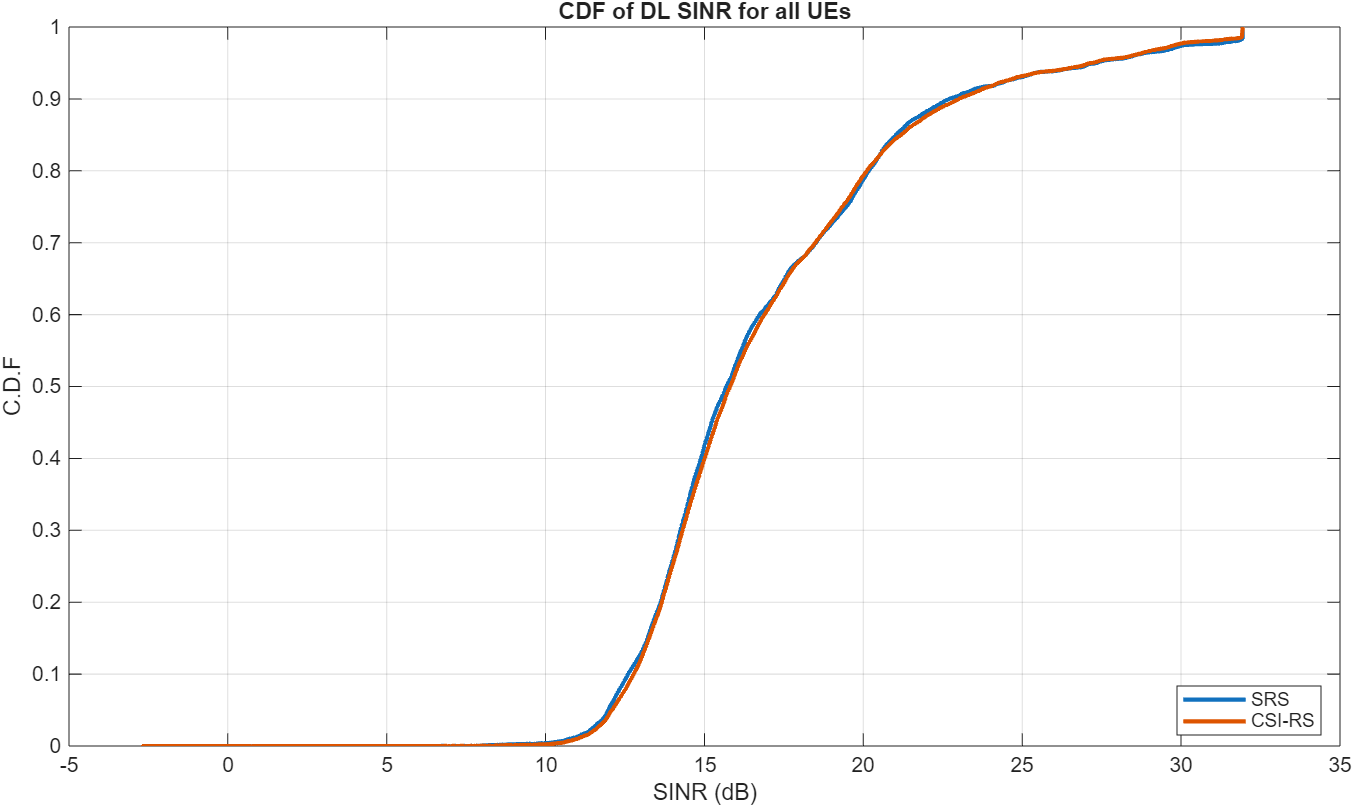

## Supporting Functions

The example uses these helpers:

- [`helperNRMetricsVisualizer`](matlab:openExample('5g/NRCellPerformanceEvaluationWithMIMOExample','supportingFile','helperNRMetricsVisualizer')): Implements metrics visualization functionality

- [`helperNRSchedulingLogger`](matlab:openExample('5g/NRCellPerformanceEvaluationWithMIMOExample','supportingFile','helperNRSchedulingLogger')): Implements scheduling information logging functionality

- [`helperNRPhyLogger`](matlab:openExample('5g/NRCellPerformanceEvaluationWithMIMOExample','supportingFile','helperNRPhyLogger')): Implements Phy packet reception information logging functionality

- [`hNRCustomChannelModel`](matlab:openExample('5g/NRCellPerformanceEvaluationWithMIMOExample','supportingFile','hNRCustomChannelModel')): Implements channel modeling functionality

- [`h38901Channel`](matlab:openExample('5g/NRIntercellInterferenceModelingExample','supportingFile','h38901Channel')): Implements the 3GPP TR 38.901 channel model

- [`hNRCreateCDLChannels`](matlab:openExample('5g/NRCellPerformanceEvaluationWithMIMOExample','supportingFile','hNRCreateCDLChannels.m')): Creates CDL channels for gNB-to-UE and UE-to-gNB links

*Copyright 2021-2025 The MathWorks, Inc*.